# Solving Ordinary Differential Equations in MATLAB

## Differential Equations in Science

- Exponential decay/growth

- Simple Harmonic Motion

- Damped, driven Harmonic Motion

- Lotka-Volterra Equations

## MATLAB ODE Solvers

- `ode45`

- `ode23`

- `ode113`

- `ode15s`

- `ode23s`

## Euler’s Method (1st Order Runge-Kutta)

Basic Method for solving a differential equations


$$\frac{dy}{dt} = f(y,t)$$


- Given an initial condition $y\left(t=0\right)=y_0$, we can find the next step in the solution $y\left(t\right)$ by


$$y(t+h) = y(t) +h\frac{dy}{dt} + \ldots$$



$$y(t+h) = y(t) +hf(y,t)$$


- But we ignored all the $h^2$ terms in the expansion

## 2nd order Runge Kutta

The second order *Runge-**Kutta *method improves on the error of the first order by considering the slope at the midpoint of the step *h*.

`¡`Consider:    $\frac{\textrm{dy}}{\textrm{dx}}=f\left(y,t\right)$, then Taylor expand around* t+h/2*


$$y(t+h) = y(t+\frac{h}{2}) + \frac{h}{2}\frac{dy}{dt}+\frac{h^2}{8}\frac{d^2y}{dt^2} + \ldots$$


Where we can derive a similar expression for *y(t),*


$$y(t) = y(t+\frac{h}{2}) - \frac{h}{2}\frac{dy}{dt}+\frac{h^2}{8}\frac{d^2y}{dt^2} + \ldots$$


- Taking the difference of the two expression gives


$$y(t+h) = y(t) + h\frac{dy}{dt} + O(h^3)$$


- The second order *Runge-**Kutta *method has a problem: you need to know y(t+h/2)- Use Euler’s method to estimate it!


$$y(t+h) = y(t) + \frac{h}{2}f(y,t)$$


- The complete method then takes three steps to estimate the next step in the solution


$$k_1 = hf(y,t)\\
k_2 = hf(y+\frac{k_1}{2},t+\frac{h}{2})\\
y(t+\frac{h}{2}) = y(t)+k_2$$


MATLAB function ode23 uses a 2nd order Runge-Kutta Method. Let's take a look at the Logistic equation that models the population over time subject to constraints, that is *P(t)<Pmax. *The logistic equation (also called the* Verhulst model* or* logistic growth curve*) is a model of population growth first published by Pierre Verhulst (1845, 1847)


$$\frac{dp}{dt} = k p \left(1 - \frac{p}{p_{max}}\right)$$


where *p *is the population function, *k* is the population growth rate, and $p_{\max }$ is a limiting factor on population.

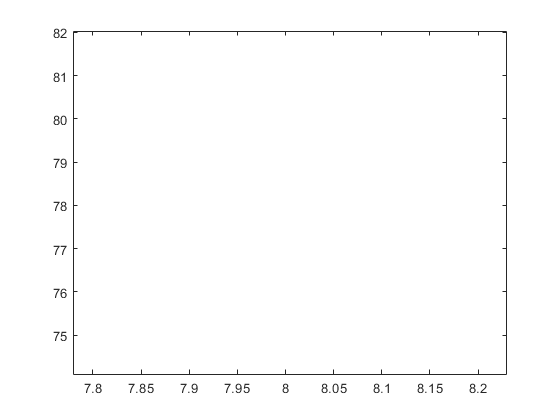

pmax = 100; % limiting population
k = 0.5; % growth rate
f = @(t,p) k*p.*(1-p./pmax);
tspan = [0 20];
[t,p] = ode23(f,tspan,10);
plot(t,p)

length(t)

ans =     16

## 4th order Runge Kutta (the sweet spot)

- Higher order Runge-KuttaMethods require more and more calculations

- The Sweet spot of ODE solvers is considered the 4th order Runge-Kutta method:

- Finds the slope at 4 points and takes a weighted average


$$k_1 = hf(y,t)\\
k_2 = h f(y+\frac{k_1}{2},t+\frac{h}{2})\\
k_3 = h f(y+\frac{k_2}{2},t+\frac{h}{2})\\
k_4 = h f(y+k_3,t+h)\\
y(t+h) = y(t)+\frac{1}{6}(k_1+2k_2 + 2k_3+k_4) $$


Iterates through a number of steps $N = \frac{y_f-y_0}{h}$ 

MATLAB function ode45 uses the 4th order Runge Kutta Method

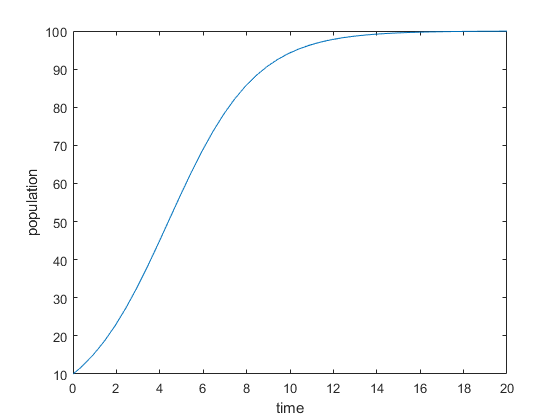

pmax = 100; % limiting population
k = 0.5; % growth rate
pdot = @(t,p) k*p*(1-p/pmax);
tspan = [0 20];
[t,p] = ode45(pdot,tspan,10);
plot(t,p)
xlabel('time')
ylabel('population')

length(t)

ans =     45

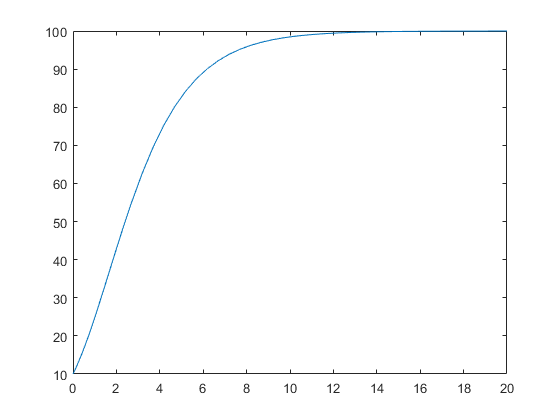

pdot2 = @(t,p) k*p*(log(pmax/p));
[t,p] = ode45(pdot2,tspan,10);
plot(t,p)

## How accurate are these methods?

*Nth *order Runge-Kutta method have an error on the order of h^(n+1)

- Euler’s Method - $\epsilon \approx {\textrm{ch}}^2$

- Midpoint Method (2nd order) - $\epsilon \approx {\textrm{ch}}^3$

- 4th order Runge-Kutta  - $\epsilon \approx {\textrm{ch}}^5$

“Then we want the smallest step possible, right?”

- **Well, do we know the answer to this yet??**

**What method does the **`ode45 `**function use?**

## MATLAB Syntax

The function `ode45` takes a number of arguments and returns the solution to the differential equation

- `@func`– is a function handle or an anonymous function

- `tspan` – specifies the range of the solution

- `y0 `– is the initial value

- `opts` – contains a number of optional arguments that can be useful

## Newton’s Heating/Cooling Law Example

This is an early model in thermodynamics that states the rate of cooling/heating of a body is proportional to the difference in temperatures of that body and its environment:


$$\frac{dT}{dt} = h\frac{A}{C}(T_{env}-T)$$


- *A* = the area of the body

- *C* = heat capacity

- *h* = heat transfer coefficient

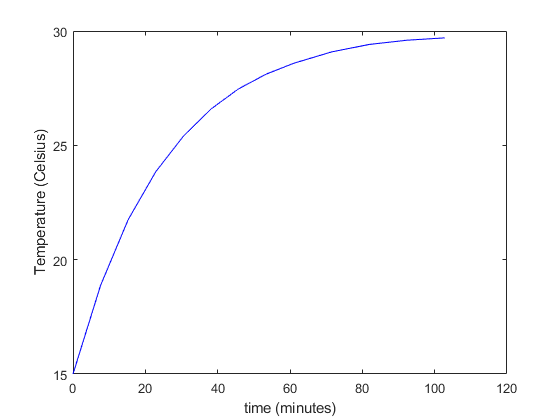

time =      1.028122761498498e+02

time = templaw(15,30,29.7)

## `Events `function

Use the `‘events' `option of the `odeset` function to specify an event function

- `value` -  is a mathematical expression describing the event.  An event occurs when `value` is equal to zero.

- `isterm` - 1 to terminate the integration when the event occurs. Otherwise, 0.

- `dir` -  0 if all zeros are to be located (the default). +1 locates only zeros where the event function is increasing, and -1 locates only zeros where the event function is decreasing

- Must input the independent and dependent variables